# Laboratorio grupal. Explorando la farmacocinética y farmacodinámica del paracetamol: un enfoque práctico en Matlab y Simulink

**Autores: **Javier Blanco Álvarez, Pablo Castañeda Fuentes, Lucía Royo Pascual, Ferrán Soto Moscardó, Jesús Gallinal Moreno

### RESUMEN

`no más de 300 palabras`

**Palabras clave:** farmacocinética, farmacodinámica, paracetamol, modelado de sistemas dinámicos, Simulink, Matlab

## 1. INTRODUCCIÓN

El paracetamol es un fármaco que suele incluirse en la clasificación de analgésicos junto con los antiinflamatorios no esteroides, aunque tiene diferencias en su acción y efectos secundarios. Algunas caracteristicas importantes a tomar en cuenta es que el paracetamol se absorbe bien en el tracto gastrointestinal de los seres humanos y se ha estimado que su biodisponibilidad oral es del 63 al 89% en comparación con la forma intravenosa (Graham, G et al, 2013). Además, se ha evidenciado que la tasa de absorción parece ser independiente de la dosis (Hodgman & Garrard, A. 2012) y, que su formulación tiene poco efecto sobre la tasa de absorción, lo que sugiere que el paracetamol se absorbe más allá del estómago y que el vaciado gástrico ocurre antes de que se produzca una absorción significativa de este (Leiper, J. 2015).

El presente trabajo tiene como objetivo analizar un modelo farmacocinético y farmacodinámico (PK/PD) del paracetamol utilizando la plataforma de simulación Simulink. Este enfoque computacional permite simular y comprender de manera detallada los procesos de absorción, distribución, metabolismo y eliminación del fármaco en el organismo, así como su relación con la respuesta terapéutica.

A través de la construcción de un modelo compartimental en Simulink, se busca representar de forma simplificada los procesos farmacocinéticos del paracetamol. Los bloques utilizados en el modelo simularán los diferentes compartimentos del organismo (plasma, tejidos periféricos, tracto gastrointestinal) y los procesos de transferencia de fármaco entre ellos. Además, se incorporará un bloque que represente el efecto farmacológico del paracetamol, permitiendo evaluar la relación entre la concentración plasmática y la respuesta terapéutica.

La simulación del modelo permitirá explorar diferentes escenarios clínicos, como el impacto de distintas dosis iniciales del fármaco en la concentración plasmática y en el tiempo necesario para alcanzar el efecto máximo. Asimismo, se analizará la influencia de la tasa de eliminación del fármaco y de la tasa de administración en la farmacocinética y farmacodinamia del paracetamol.

Este trabajo se estructura en las siguientes secciones: en primer lugar, se describirá en detalle el desarrollo del modelo en Simulink, incluyendo la justificación de la elección de los compartimentos y los parámetros utilizados. A continuación, se presentarán los resultados de las simulaciones y se discutirán las implicaciones clínicas de los mismos. Finalmente, se expondrán las conclusiones y las limitaciones del estudio, así como las posibles líneas de investigación futuras.

**Objetivos**

Los objetivos del trabajo son los siguientes:

- Evaluar el impacto del cambio en la dosis inicial del fármaco en las concentraciones plasmáticas y efectivas a lo largo del tiempo, analizando cómo diferentes dosis afectan la cinética del fármaco y su efecto terapéutico.

- Investigar cómo la tasa de eliminación del fármaco (parámetro K) afecta la duración y magnitud del efecto terapéutico, examinando cómo variaciones en la tasa de eliminación influyen en las concentraciones plasmáticas y efectivas del fármaco.

- Analizar el efecto de ajustar la tasa de infusión (parámetro F) en las concentraciones plasmáticas y efectivas del fármaco, explorando cómo diferentes tasas de administración impactan en la cinética del fármaco y su efecto terapéutico.

- Utilizar herramientas de modelado y simulación, como MATLAB y Simulink, para estudiar el comportamiento del fármaco en el organismo. Mediante la aplicación de técnicas de simulación, podrán comprender mejor los principios subyacentes de la farmacocinética y la farmacodinamia.

**Descripción**

En este laboratorio, se emplea un enfoque de dos compartimentos para describir tanto la farmacocinética (PK) como la farmacodinámica (PD) de un fármaco. En este contexto, el primer compartimento representa el plasma, que actúa como un depósito inicial del fármaco en la circulación sistémica, mientras que el segundo compartimento puede referirse a tejidos u otros órganos del cuerpo donde el fármaco se distribuye y ejerce su efecto.

 Este enfoque de dos compartimentos nos permite comprender cómo el fármaco se absorbe, se distribuye, se metaboliza y se elimina en el organismo, así como cómo estos procesos se relacionan con su efecto farmacológico.

 Las ecuaciones diferenciales asociadas con este modelo nos proporcionan una herramienta para simular y estudiar cómo varían las concentraciones de fármaco en el tiempo en diferentes compartimentos del cuerpo, así como su efecto biológico en el sitio de acción. 

 Las ecuaciones diferenciales que gobiernan el modelo son las siguientes:


$$\frac{dC_{gut} }{dt}=\ {-K}_a C_{gut}$$



$$\frac{dC_1 }{dt}=-k_{12} C_1 +k_{21} C_2 -KC_1 +FK_a C_{gut}$$



$$\begin{array}{l}
\frac{dC_2 }{dt}=\ k_{12} C_1 -k_{21} C_2 \\
\frac{dC_e }{dt}=\ k_{e1} C_1 -k_{e0} C_e 
\end{array}$$


 Las variables del modelo incluyen $C_1$, que representa la concentración de la droga en el compartimento 1, generalmente asociado con el plasma sanguíneo o algún otro compartimento central del organismo. Por otro lado, $C_2$ denota la concentración de la droga en el compartimento 2, el cual puede simbolizar tejidos periféricos u otros compartimentos del cuerpo. Además, $C_{gut}$ refleja la concentración de la droga en el compartimento gastrointestinal, indicando la cantidad de fármaco presente en el tracto gastrointestinal en un momento dado. Finalmente, $C_e$ representa la concentración efectiva de la droga, caracterizando la cantidad de droga presente en el sitio de acción o su efecto biológico.

 Por otro lado, los parámetros del modelo comprenden $K$, que representa la constante de eliminación de la droga del compartimento 1 (plasma), indicando la velocidad a la que la droga abandona este compartimento. Además, $k_{12}$ y $k_{21}$ representan las tasas de transferencia de la droga entre el compartimento 1 y el compartimento 2, respectivamente, describiendo cómo la droga se mueve entre estos dos compartimentos. $K_a$ denota la tasa de absorción de la droga desde el tracto gastrointestinal al compartimento 1, mientras que $k_{e1}$ y $k_{\textrm{e0}}$son las tasas de eliminación de la droga desde el compartimento 1 y el compartimento efectivo, respectivamente. Finalmente, $F$ representa la fracción de la dosis que se absorbe en el tracto gastrointestinal y contribuye al compartimento 1. Los valores de los parámetros se recogen en la tabla siguiente:

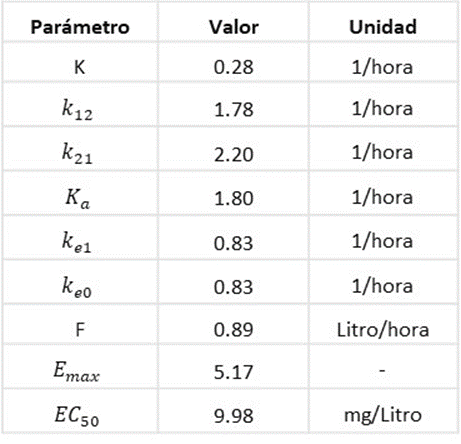

Tabla 1. Fuente: elaboración propia. 

Las principales propiedades farmacodinámicas comprenden el efecto máximo ($E_{max}$) y la concentración que genera el 50 % del máximo efecto ($EC_{50}$). La relación entre la concentración del fármaco y su efecto puede ser descripta mediante la ecuación de Hill [3],


$$Effect=E_0 -\frac{E_{max\ } \ C_e^n }{EC_{50}^n \ \ +\ \ C_e^n }$$


donde  representa la respuesta basal,  indica el cambio máximo en el efecto,  es la concentración en el compartimento del efecto,  es la concentración que produce el 50 % de , y   es el coeficiente de Hill [3], que define la pendiente de la curva. En este laboratorio,  y .

**Preguntas**

- Desarrolle el modelo en Simulink, mostrando los diversos bloques que componen la estructura del sistema. Proporcione una captura de pantalla del modelo de bloques resultante, identificando y explicando la función de cada bloque utilizado en la simulación del modelo PK/PD. 

- Configure el tiempo de simulación en ocho horas para investigar las variaciones iniciales de las concentraciones plasmáticas y efectivas del paracetamol poco después de su administración. Para las condiciones iniciales, podríamos establecer que la concentración inicial en el compartimento 1 es de 1000mg/L, mientras que las demás concentraciones se establecen en cero excepto la concentración inicial en el compartimento de Gut que se encuentra en 200mg/L. Esta configuración permite explorar cómo los residuos de fármacos no absorbidos en el tracto gastrointestinal pueden afectar la absorción y distribución del paracetamol en el organismo, proporcionando una perspectiva más completa de su cinética y efecto terapéutico.

- ¿Cómo afecta el cambio en la dosis inicial del fármaco a las concentraciones plasmáticas y efectivas a lo largo del tiempo? Comparemos el impacto de diferentes dosis iniciales de paracetamol (por ejemplo, 400 mg, 600 mg y 1000 mg) mediante medidas estándar, como la concentración plasmática máxima (Cmax), el tiempo necesario para alcanzarla (Tmax), el área bajo la curva de concentración plasmática frente al tiempo (AUC) y la concentración efectiva en momentos específicos, como el instante en que se alcanza el efecto máximo (Emax).

- ¿Cómo afecta la tasa de eliminación del fármaco (parámetro ) a la duración y magnitud del efecto terapéutico?

- ¿Cómo varía la concentración plasmática del fármaco en respuesta a cambios en la tasa de administración (parámetro )?

**Modelo Simulink y Matlab**

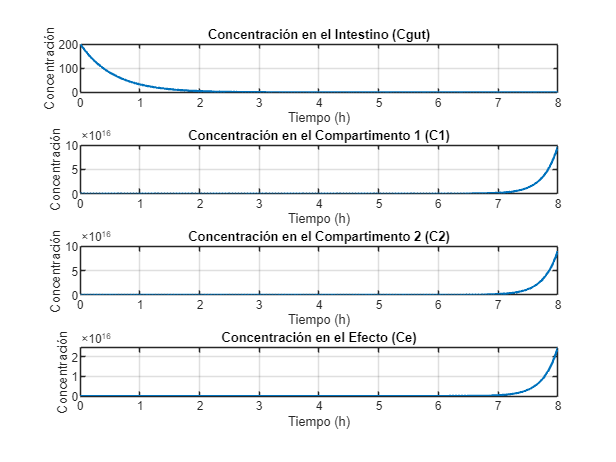

clc; clear all;

% Cargar y configurar el modelo de Simulink
modelo = 'Laboratorio_grupal_simulink'; % Nombre del modelo (sin extensión .slx)
load_system(modelo); % Cargar el modelo en MATLAB

%SIMULACIÓN T=8h
% Configurar parámetros de simulación si es necesario
set_param(modelo, 'StopTime', '8'); % Configurar tiempo de simulación (opcional)

% Ejecutar la simulación
out = sim(modelo);

%Extracción de variables
Cgut = out.Cgut; % Valores de Cgut
C1 = out.C1; % Valores de C1
C2 = out.C2; % Valores de C2
Ce = out.Ce; % Valores de Ce
effect=out.effect;

%Plots
% Crear los subplots
figure;

% Subplot 1: Concentración en el intestino (Cgut)
subplot(4,1,1);
plot(Cgut.Time, Cgut.Data, 'LineWidth', 1.5);
title('Concentración en el Intestino (Cgut)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 2: Concentración en el compartimento 1 (C1)
subplot(4,1,2);
plot(C1.Time, C1.Data, 'LineWidth', 1.5);
title('Concentración en el Compartimento 1 (C1)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 3: Concentración en el compartimento 2 (C2)
subplot(4,1,3);
plot(C2.Time, C2.Data, 'LineWidth', 1.5);
title('Concentración en el Compartimento 2 (C2)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 4: Concentración en el efecto (Ce)
subplot(4,1,4);
plot(Ce.Time, Ce.Data, 'LineWidth', 1.5);
title('Concentración en el Efecto (Ce)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

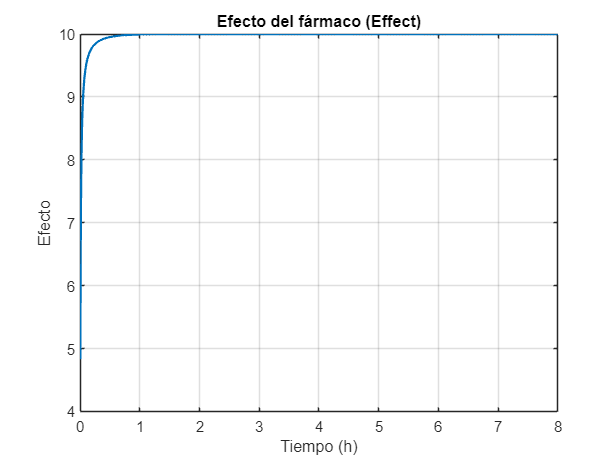

%CALCULO DE EFECTO MAXIMO
%Plots
figure;

plot(effect.Time, effect.Data, 'LineWidth', 1.5);
title('Efecto del fármaco (Effect)');
xlabel('Tiempo (h)');
ylabel('Efecto');
grid on;

### 2. Distribución y absorción del fármaco como consecuencia de la acumulación de residuos. 

Para entender el efecto de la acumulación de residuos en el tracto gastrointestinal se ejecuta una simulación de 8hrs. La simulación requiere de concentraciones inicial de 1000mg/L para el primer compartimento y de 200mg/L para la concentración en el tracto intestinal o Cgut. El resto de concentraciones iniciales se toman a cero. Por ello ejecutamos el modelo con estas concentraciones iniciales para estudiar la evolución del paracetamol en el organismo y su cantidad efectiva.

clc; clear all;

% Cargar y configurar el modelo de Simulink
modelo = 'Laboratorio_grupal_simulink'; % Nombre del modelo (sin extensión .slx)
load_system(modelo); % Cargar el modelo en MATLAB

%SIMULACIÓN T=8h
% Configurar parámetros de simulación si es necesario
set_param(modelo, 'StopTime', '8' ); % Configurar tiempo de simulación (opcional)

% Ejecutar la simulación
out = sim(modelo);

%Extracción de variables
Cgut = out.Cgut; % Valores de Cgut
C1 = out.C1; % Valores de C1
C2 = out.C2; % Valores de C2
Ce = out.Ce; % Valores de Ce
effect=out.effect;

%Plots
% Crear los subplots
figure;

% Subplot 1: Concentración en el intestino (Cgut)
subplot(4,1,1);
plot(Cgut.Time, Cgut.Data, 'LineWidth', 1.5);
title('Concentración en el Intestino (Cgut)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 2: Concentración en el compartimento 1 (C1)
subplot(4,1,2);
plot(C1.Time, C1.Data, 'LineWidth', 1.5);
title('Concentración en el Compartimento 1 (C1)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 3: Concentración en el compartimento 2 (C2)
subplot(4,1,3);
plot(C2.Time, C2.Data, 'LineWidth', 1.5);
title('Concentración en el Compartimento 2 (C2)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 4: Concentración en el efecto (Ce)
subplot(4,1,4);
plot(Ce.Time, Ce.Data, 'LineWidth', 1.5);
title('Concentración en el Efecto (Ce)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

Permitiendo el estudio del efecto del fármaco como:

%CALCULO DE EFECTO MAXIMO
%Plots
figure;

plot(effect.Time, effect.Data, 'LineWidth', 1.5);
title('Efecto del fármaco (Effect)');
xlabel('Tiempo (h)');
ylabel('Efecto');
grid on;

### 5. Efecto del cambio de la tasa de administración del fármaco (Ka) en la concentración plamática. 

Para el estudio de la infuencia que tiene la tasa de administración del fámarco (Ka) en la concentración del compartimento 1 (plasmática), ejecutaremos el modelo farmacodinámico implementado en Simulink para 6 valores distintos de Ka. La tasa de administración Ka controla la concentración del fármaco en el tracto intestinal donde las moléculas de este se han de difundir hasta ponerse en contacto con la región apical de los enterocitos y posteriormente atravesar una serie de barreras para alcanzar la circulación sistémica  o compartimento 1 (Stenberg P, et al. 2002). El propósito de este analisis es observar cambio en el perfil de concentración del fármaco, en este caso, el paracetamol, ante distintas constantes de absorción del tracto intestinal. 

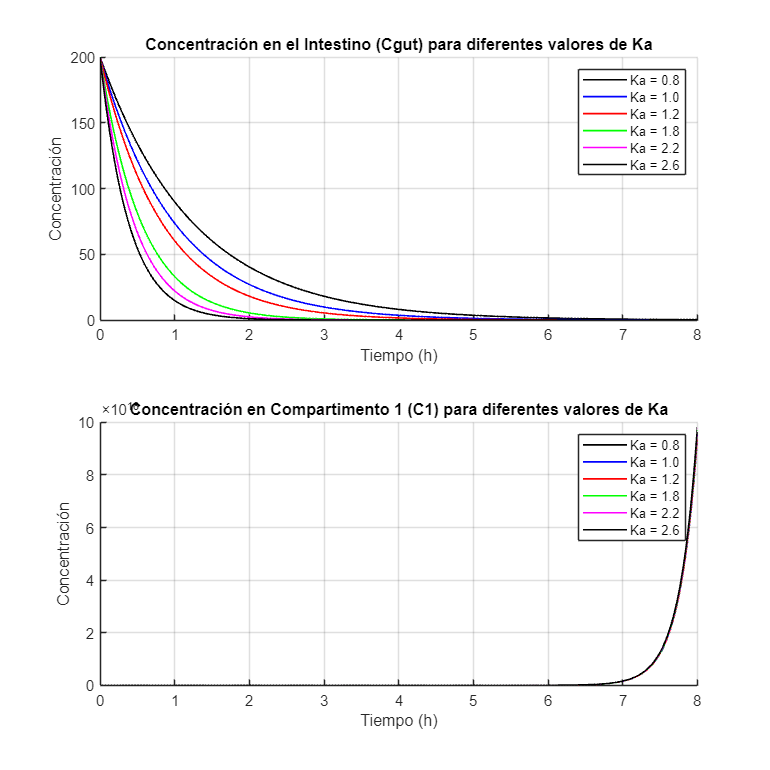

% clc; clear all;
% modelo = 'Laboratorio_grupal_simulink';
% load_system(modelo);

% Distintos valores de Ka
gain_values = [0.80 1.0 1.2 1.8 2.2 2.6];

% Gráficos
% figure;
figure('Position', [100, 100, 700, 700]);

% Para Cgut (Concentración gastrointestinal)
subplot(2,1,1);
hold on;
title('Concentración en el Intestino (Cgut) para diferentes valores de Ka');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Para C1 (Concentración en el compartimento 1 o compartimento plasmático)
subplot(2,1,2);
hold on;
title('Concentración en Compartimento 1 (C1) para diferentes valores de Ka');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Colores para cada línea
colors = {'k', 'b', 'r', 'g', 'm', 'k'};

for i = 1:length(gain_values)
    set_param([modelo '/Ka'], 'Gain', num2str(gain_values(i)));
    
    % Run simulación con el mismo tiempo establecido (8 h)
    set_param(modelo, 'StopTime', '8');
    out = sim(modelo);
    
    % Extraemos datos del workspace
    Cgut = out.Cgut;
    C1 = out.C1;
    
    % Graficar Cgut y C1 vs Tiempo
    subplot(2,1,1);
    plot(Cgut.Time, Cgut.Data, 'Color', colors{i}, 'LineWidth', 1.1);
    
    subplot(2,1,2);
    plot(C1.Time, C1.Data, 'Color', colors{i}, 'LineWidth', 1.1);
end

% Leyendas
subplot(2,1,1);
legend(cellstr(num2str(gain_values', 'Ka = %.1f')));

subplot(2,1,2);
legend(cellstr(num2str(gain_values', 'Ka = %.1f')));

% Restablecer el valor original de Ka
set_param([modelo '/Ka'], 'Gain', '1.8');


Del grafico anterior se desprende que ante distintos valores de Ka, no hay cambios significativos en la concentración del paracetamol en el compartimiento plasmático (C1) (**gráfico inferior**). Si bien **Ka** representa la velocidad a la que el fármaco se absorbe desde el intestino al compartimento central. Al aumentar Ka, se acelera la absorción, lo que provoca una disminución más rápida de la concentración en el intestino (Cgut) y un aumento más rápido en el compartimento central (C1). Sin embargo, la magnitud del cambio en C1 depende de otros parámetros como el volumen de distribución del compartimento central, la tasa de eliminación (Constante K) y las tasas de transferencia entre compartimentos.

En este experimento la constante K es muy inferior a la tasa de absorción intestinal (Ka). Esto limita el gradiente de concentración del Paracetamol entre el tracto intestinal y C1. Además, la fracción de la dosis que absorbe el intestino F, ha permanecido constante, contribuyendo a los resultados mostrados en la grafica analizado. 

Por otro lado, donde si se observa un cambio significativo en en el perfil de concentración del paracetamol con los cambios de Ka es en el tracto intestinal **(grafico superior**). Este comportamiento es esperable ya que a mayores valores de Ka, más rápida es la absorción (o eliminación) en el lumen intestinal; esto debido al gradiente negativo de la concentración gobernada por la expresión:


$$\frac{dC_{gut}}{dt} = -K_a C_{gut} \\
\frac{dC_1}{dt} = -k_{12}C_1 + k_{21}C_2 - KC_1 + FK_a C_{gut}$$


Mientras la constante de eliminación K en C1 sea inferior a Ka (K<Ka) y la fracción de dosis absorbida desde el intestino (F) sea constante, el perfil de concentración en C1 con respecto al tiempo no se verá impactado de manera significativa.

## CONCLUSIONES

El paracetamol es un analgésico y antipirético eficaz, pero su modo de acción aún no se comprende completamente. El nivel plasmático obtenido depende de la vía de administración (Ward, B & Alexander J, 1999). [...] `continuar cuando se obtengan los demás resultados del resto de compañeros`

De los resultados graficados para cada compartimento estudiado podemos extraer ciertas conclusiones. La concentración en el tracto gastrointestinal, denotado por Cgut, observamos una absorción en la primeras dos horas. Este comportamiento aparece como una asíntota a cero en con el tiempo, estabilizando la concentración deste la hora 2 en adelante.

La concentración en el resto de compartimientos definidos en el modelo es similar. Observando el incremento en la concentración a partir de la hora 7, con un comporatmiento rápidamente creciente. Teniendo en cuenta que una concentración excesiva del fármaco a partir de la séptima hora puede ser tóxico. Se puede comporabar que la concentración en C1 y en C2 tiene un comportamiento en un orden de e16. La Concentración en el efecto también presenta un comportamiento en el mísmo orden de concentraciones. Claramente los valores se diferencian en un producto 5. Donde los valores para C1 y C2 están se aproximan a 10 elevado a 17; siendo la Concentración en el efecto de 2 elevado a 16.

En cuanto al estudio del efecto del fármaco se puede comporbar que alcanzamos el efecto máximo en la primera hora. Es por ello que si el modelo está describiendo correctamente el comportamiento del fármaco y su farmacocinética los efectos tóxicos del mismo puede incurrir en daños al sistema en la forma de fallo en el hígado y riñones, bajo azúcar en sangre o pancreatitis Jones A (2002).

En cuanto al analisis de la influencia de la tasa de adsorción del fármaco Ka sobre la concentración en el compartimiento 1, algunos autores opinan que la absorción intestinal de un fármaco depende, principalmente, de factores tales como la solubilidad del mismo fármaco, de su proceso de disolución, de su permeabilidad a través de la mucosa intestinal y del tiempo de tránsito intestinal (Aungst, 2000; Hidalgo, 2001). Este enfoque justificaria el comportamiento en el perfil C1 encontrado tras las variaciones de Ka. Además que el compartimento C1 se ve influenciado por otros factores como la constante de eliminación del compartimento 1 (K); si K es grande, el fármaco se elimina rápidamente del compartimento central, lo que limita el aumento de C1, incluso si la tasa de absorción (Ka) es alta. Además de las tasas de transferencia entre compartimentos (k12 y k21) también influyen en la distribución del fármaco y, por lo tanto, en la concentración en C1.

## REFERENCIAS

- Stenberg P, Bergstrôm C, Luthman K, Artursson P. Theoretical predictions of drug absorption in drug discovery and development. Clin Pharmacokinet. 2002; 41(11):877-899.

- Graham, G. G., Davies, M. J., Day, R. O., Mohamudally, A., & Scott, K. F. (2013). The modern pharmacology of paracetamol: therapeutic actions, mechanism of action, metabolism, toxicity and recent pharmacological findings. *Inflammopharmacology*, *21*, 201-232.

- Aungst B. Intestinal permeation enhancers. J Pharm Sci. 2000; 89:429-442.

- Hodgman, M. J., & Garrard, A. R. (2012). A review of acetaminophen poisoning. *Critical care clinics*, *28*(4), 499-516.

- Hidalgo I. Assessing the absorption of new pharmaceuticals. Curr Top Med Chem. 2001; 1:385-401.

- Ward, B., & Alexander-Williams, J. M. (1999). Paracetamol revisited: a review of the pharmacokinetics and pharmacodynamics. *Acute Pain*, *2*(3), 139-149.

- Leiper, J. B. (2015). Fate of ingested fluids: factors affecting gastric emptying and intestinal absorption of beverages in humans. *Nutrition reviews*, *73*(suppl_2), 57-72.

- Jones A (2002). "Over-the-counter analgesics: a toxicology perspective". *Am J Ther*. **9** (3): 245–57. 